# Aula 9 - Laboratório de Controle - 2023/1

## Controle de velocidade do motor CC usando controlador PI e PID

## **Nomes:   **

**IMPORTANTE: não dê o comando RUN nesta aula, pois pode perder tudo o que fez!!!!**

**Execute uma seção de cada vez.**

**Veja as notas no arquivo Sintonia_PID.pdf sobre a sintonia lambda.**

**Assista o **[video](https://youtu.be/aEhYTPk_hx4)**  para orientações sobre o projeto do controlador PI via LR para um modelo de ordem 1.**

if ~exist('obj')
    z=seriallist;
    comPort=z{length(z)};
    obj=serial(comPort,'BaudRate',9600);
    obj.Terminator='CR';
    fopen(obj);
end
datetime

**Obtenção da resposta de velocidade do motor CC **

Este teste verifica o bom funcionamento do motor e fornece os parâmetros iniciais para definir a velocidade de operação.

Execute a seção abaixo.

Ts=20;
Tempo=1;
U0=[70 100 170]; 
[y,t, yr, tau] = arduino_coleta_motor(obj,U0,Tempo);
seta_saida_motor(obj,0); 
figure;
plot(y);title('Figura 1. Resposta para a aplicação de degraus de mesma amplitude em MA');
xlabel('Amostras');ylabel('RPM')
RPM=yr;
U00=U0;

**Obtenção dos dados para o modelo que relaciona o sinal PWM com a velocidade em RPM**

Escolha uma velocidade Ref em torno da qual o motor deverá operar, a partir da observação da Figura 1. 

O próximo teste gerará dados (dat1) em torno deste ponto de operação para obter os modelos.

Basta executar a seção a seguir.  Caso os dados fiquem ruins, repita a coleta de dados.

Ref=0; % Escolha antes um valor de Ref para velocidade
Tempo=2; 
r0=floor(interp1(RPM,U00,Ref));
if isnan(r0)
    beep
    disp('**** Escolha ruim ***')
    return
end
d1=[0 0 5 10 5 8];
U20=r0+d1; 
u0=ones(100,1);
U2=[];
for i=1:6
    U2=[U2;u0*U20(i)];
end
[y,t,yr,tau] = arduino_coleta_motor(obj,U20,Tempo);
seta_saida_motor(obj,0); 

U2=U2(100:end);
Y2=y(100:end);
t=[0:(length(Y2)-1)]*Ts/1000;
y0=mean(Y2(1:50));
yn=Y2-y0;
dat1=iddata(yn,U2-U2(1),Ts/1000); 

figure;
plot(t,Y2);title('Figura 2. Resposta para a região de operação escolhida');
xlabel('Amostras');
figure;
plot(t,U2);title('Figura 3. Degraus aplicados');
xlabel('Amostras');

Nesta seção são obtidos os modelos de ordem 1 e 2.

g1e=procest(dat1,'P1');
g2e=procest(dat1,'P2');
g1=tf(g1e.Kp,[g1e.Tp1 1])
figure;
compare(dat1,g1e,g2e);
title('Figura 4: Avaliação do modelo obtido');

Na seção abaixo há outra alternativa para estimar o modelo de ordem 2, caso tenha ficado ruim. 

Escolha uma das alternativas  para obter este modelo.

g2ea=arx(dat1,[2 2 1]);
ys=step(g2ea);
dat1s=iddata(ys,ones(size(ys)),Ts/1000);
g2e=procest(dat1s,'P2');
figure;
compare(dat1,g2e);

**Atividade 1: Controle do motor CC com controlador PI obtido via sintonia lambda**

Seja a FT de MA obtida (g1) e C o controlador cujos parâmetros são dados na tabela abaixo. 

Para os três modelos de processos abaixo tem-se em malha fechada $M(s)=\frac{C(s)G(s)}{1+C(s)G(s)}=\frac{1}{\lambda s + 1}$. 

Ou seja, a resposta em malha fechada é dada pelo sistema de ordem 1 definido pelo modelo de referência $M(s)=\frac{1}{\lambda s + 1}$, cuja constante de tempo de malha fechada é $\lambda$.

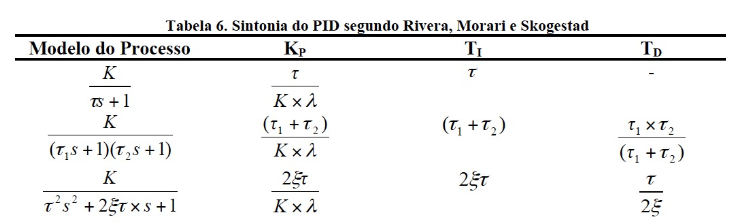

Usaremos inicialmente um modelo de ordem 1, pois como se observa na Tabela, um modelo de ordem 2 requer um controlador PID para que a resposta em malha fechada seja dada por $M(s)$.

Assim, para  $g_1(s)=\frac{K}{\tau s + 1}$, usaremos o controlador PI dado por $C(s)=K_p+K_p K_I/s=K_p\frac{s+K_I}{s}$, um controlador PI série, em que $K_p$ multiplica $K_i$

**Comentários sobre o código abaixo:**

**Inicialização**: quando executada, zera todos os testes.

**Testar valor de lambda**: escolha um valor  de lambda e execute a seção. Este valor será usado para projetar o controlador PI e testá-lo no motor. 

**Incluir teste**: caso deseje armazenar o resultado do teste para o valor de lambda escolhido, execute esta seção.  Ao fazê-lo, os valores são armazenados e mostrados junto com os demais testes. Pode-se então voltar a testar novos valores de lambda.

**Tabela com resultados**: Mostra uma tabela que resume os valores de sobreelevação (UP), tempo de estabelecimento (ts) e IAE para cada valor de lambda testado.

**Inicialização: **zera todos os testes.

Tempo=2;
K=g1e.K;
tau=g1e.Tp1;
Ref1=Ref+200;
Y=[];
Uc=[];
leg=[];
UP=[];
ts=[];
IAE=[];
Lambda=[];

**Testar valor de lambda**

Verifique qual a constante de tempo de malha aberta de g1, e escolha valores para $\lambda$ de modo que o controlador PI obtido gere respostas mais rápidas que em malha aberta, porém com uma sobreelevação limitada. Teste pelo menos 5 valores de lambda, com respostas mais e menos rápidas.

Escolher um valor para lambda e executar a seção.

lambda=0;
if (lambda<=0)
    beep;
    disp('lambda deve ser > 0');
    return
end
Kp=tau/(K*lambda); 
Ki=1/tau;
[y,u,t] = arduino_controle_PI_motor(obj,Ref,Tempo, Kp, Ki); 
[y,u,t] = arduino_controle_PI_motor(obj,Ref1,Tempo, Kp, Ki); 
seta_saida_motor(obj,0);
r=Ref1*ones(size(y));
figure;
subplot(211);plot(t,[y r]);title('Figura 5. Resposta para lambda selecionado');
subplot(212);plot(t,u);title('Figura 6. Sinal de controle para lambda selecionado');
 

**Incluir teste**: 

Execute esta seção para armazenar o resultado do teste da seção anterior.

nr=Ref1-mean(y(1:3));
iae=trapz(t,100*abs(Ref1-y)/nr); % IAE normalizado pela referencia
S=stepinfo(y,t);
Lambda=[Lambda;lambda];
IAE=[IAE;iae];
UP=[UP;S.Overshoot];
ts=[ts;S.SettlingTime];
leg=[leg;num2str(lambda,'%3.2f')];
Y=[Y y];
Uc=[Uc u];
figure;
stairs(t,[Y r]);
title('Figura 7. Resposta para os valores de lambda selecionados');
legend(leg);
xlabel('Tempo(s)');
figure;
stairs(t,Uc);
title('Figura 8. Sinal de controle para os valores de lambda selecionados');
legend(leg);
xlabel('Tempo(s)');


**Resumo dos testes**

Tabela1=table(Lambda,UP,ts,IAE)


1.1 Qual a resposta mais rápida que conseguiu e qual foi a limitação?

1.2 Que valor de lambda deu o melhor desempenho? Caracterize-o pelos valores mostrados na Tabela 1.

1.3 Que o efeito da redução de lambda sobre o IAE?

**Atividade 2: Controle do motor CC com controlador PID e sintonia lambda**

Use agora o modelo de ordem 2 (g2), que tem dois polos (reais ou complexos). Para ter-se $M(s)=\frac{1}{\lambda s + 1}$, o controlador resultante é um PID (veja a Tabela 6).

2.1 Escolha o mesmo valor de lambda que deu o melhor resultado com o controlador PI, e compare o desempenho dos controladores PI e PID.

lambda=0; % Escolher valor de lambda
g2=g2e;
[~,z]=damp(g2);
g2complexo=z<1;
if g2complexo     % g2 tem polos complexos
    K=g2.K;
    tau=g2.Tw;
    zeta=g2.Zeta;   
    Kp=2*zeta*tau/(K*lambda); % Sintonia lambda
    Ki=1/(2*zeta*tau);
    Kd=tau/(2*zeta);
    G2=tf(K,[tau^2 2*zeta*tau 1]);
else              % g2 tem polos reais
    K=g2.K;
    tau1=g2.Tp1;
    tau2=g2.Tp2;
    Kp=(tau1+tau2)/(K*lambda); % Sintonia lambda
    Ki=1/(tau1+tau2);
    Kd=(tau1*tau2)/(tau1+tau2);
    G2=tf(K,conv([tau1 1],[tau2 1]));
end

[y,u,t] = arduino_controle_PID_motor(obj,Ref,Tempo, Kp, Ki, Kd); % teste
[y,u,t] = arduino_controle_PID_motor(obj,Ref1,Tempo, Kp, Ki, Kd); % teste
seta_saida_motor(obj,0);

nr=Ref1-mean(y(1:3));
iae=trapz(t,100*abs(Ref1-y)/nr);
S=stepinfo(y,t);
up2=S.Overshoot;
ts2=S.SettlingTime;
ss=sprintf('Figura 9. Saída para controlador PID - IAE = %.0f',iae);
figure;
subplot(2,1,1);
r=Ref1*ones(size(y));
stairs(t,[y r]);title(ss);xlabel('Tempo(s)');ylabel('RPM');
subplot(2,1,2);
stairs(t,u);title('Figura 10. Sinal de Controle');xlabel('Tempo(s)');
tabela2=table(lambda,up2,ts2,iae)

Agora compare o desempenho dos controladores PI e PID.

2.2 Há evidências de que se pode conseguir um desempenho melhor usando o controlador PID e outro valor de lambda, baseado nos testes anteriores?

Justifique e teste abaixo com um novo valor de lambda.

lambda=0; % Escolher valor de lambda
g2=g2e;
if g2complexo     % g2 tem polos complexos
    K=g2.K;
    tau=g2.Tw;
    zeta=g2.Zeta;   
    Kp=2*zeta*tau/(K*lambda); % Sintonia lambda
    Ki=1/(2*zeta*tau);
    Kd=tau/(2*zeta);
else              % g2 tem polos reais
    K=g2.K;
    tau1=g2.Tp1;
    tau2=g2.Tp2;
    Kp=(tau1+tau2)/(K*lambda); % Sintonia lambda
    Ki=1/(tau1+tau2);
    Kd=(tau1*tau2)/(tau1+tau2);
end

[y,u,t] = arduino_controle_PID_motor(obj,Ref,Tempo, Kp, Ki, Kd);
[y,u,t] = arduino_controle_PID_motor(obj,Ref1,Tempo, Kp, Ki, Kd);
seta_saida_motor(obj,0);

nr=Ref1-mean(y(1:3));
iae=trapz(t,100*abs(Ref1-y)/nr);
S=stepinfo(y,t);
up2=S.Overshoot;
ts2=S.SettlingTime;
ss=sprintf('Figura 11. Saída para controlador PID - IAE = %.0f',iae);
figure;
subplot(2,1,1);
r=Ref1*ones(size(y));
stairs(t,[y r]);title(ss);xlabel('Tempo(s)');ylabel('RPM');
subplot(2,1,2);
stairs(t,u);title('Figura 12. Sinal de Controle');xlabel('Tempo(s)');
tabela3=table(lambda,up2,ts2,iae)

**Atividade 3: Projeto do controlador PI via método do lugar das raízes**

Lembramos que a função de transferência do controlador PI é dada por $C(s)=K_p+K_p K_I/s=K_p\frac{s+K_I}{s}$. Logo, com os valores de $K_p$ e $K_i$ do projeto via sintonia lambda pode-se identificar a localização do zero em $s=-K_I$ naquele projeto. 

3.1 A partir desta escolha, use o rltool ou sisotool  para buscar uma nova escolha do zero e do ganho $K_p$ para obter um controlador PI com IAE melhor que o obtido na Tabela 1. Escolha o modelo que julgar melhor para fazer o projeto, de ordem 1 (g1) ou de ordem 2 (G2). Substitua os valores de $K_p$ e $K_i$ abaixo e mostre o resultado obtido.

Explique como fez as escolhas e a razão para o sucesso ou insucesso, comparando a tabela 4 com a tabela 3.

Kp=0; % Substituir pelos obtidos do LR
Ki=0; % Substituir pelos obtidos do LR
[y,u,t] = arduino_controle_PI_motor(obj,Ref,Tempo, Kp, Ki); 
[y,u,t] = arduino_controle_PI_motor(obj,Ref1,Tempo, Kp, Ki); 
seta_saida_motor(obj,0);

nr=Ref1-mean(y(1:3));
iae=trapz(t,100*abs(Ref1-y)/nr);
S=stepinfo(y,t);
up2=S.Overshoot;
ts2=S.SettlingTime;
ss=sprintf('Figura 13. Saída para controlador PID - IAE = %.0f',iae);
figure;
subplot(2,1,1);
r=Ref1*ones(size(y));
stairs(t,[y r]);title(ss);xlabel('Tempo(s)');ylabel('RPM');
subplot(2,1,2);
stairs(t,u);title('Figura 14. Sinal de Controle');xlabel('Tempo(s)');
tabela4=table(lambda,up2,ts2,iae)

3.2 O valor de $K_i$ atribuido acima será utilizado abaixo para obter a FT de malha aberta C(s)G(s) com $K_p=1$  para desenhar o lugar das raízes utilizado. Faça o LR na linha de comando com o comando rlocus(C*G), marque sobre ele onde estão os polos de malha fechada, correspondentes ao ganho $K_p$ escolhido no projeto, que deve aparecer no lugar selecionado. Copie a figura deste LR abaixo.

% G=g1 ou G=G2;
C=tf([ 1 Ki],[1 0]);
figure;
%rlocus(C*G) % dar este comando no workspace para acessar a figura

3.3 Compare o projeto do controlador PI via método de sintonia lambda e via método do lugar das raízes, destacando aspectos como: simplicidade, flexibilidade, formas de especificação de projeto.